## LEAKY INTEGRATE-AND-FIRE

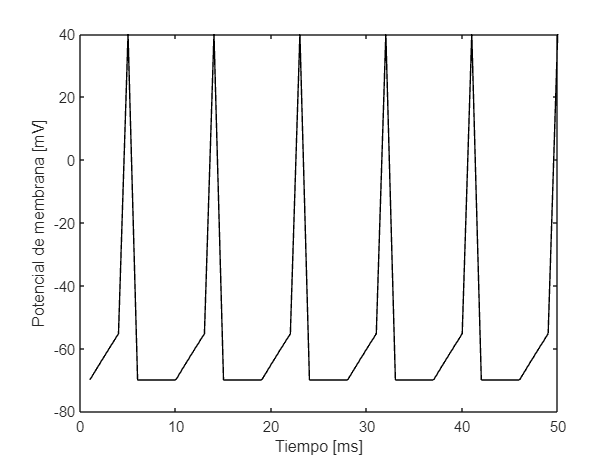

I = 5; C = 1; R = 50; n = 50; 
V = zeros(1, n); V(1) = -70; 
abs_ref = 5; ref = 0;      
V_d = -55; V_r = -70; V_p = 40;     

for i = 2:n
    if ref == 0        
        V(i) = V(i - 1) - ((V(i - 1) - V_r) / (R * C)) + (I / C); 
    else                
        ref = ref - 1;  
        V(i) = V_r;     
    end
    if V(i) > V_d       
        V(i) = V_p;     
        ref = abs_ref;  
    end
end

plot(V, 'k')
xlabel('Tiempo [ms]');
ylabel('Potencial de membrana [mV]');